# Projet M2 AURO EKF-SLAM

clc
clear all
close all

### Creation de la carte

La carte est composée de 8 amers dont le robot ne connait pas l'emplacement a priori. Nous allons créer une matrice 2x8 contenant la l'abscisse et l'ordonnnées de la position de chaque amer.


% Matrice contenant les position (X,Y) de chaque amer
Lm=[3, 5, 7, 9, 3, 5, 7, 9 ; 4, 4, 4, 4, 2, 2, 2, 2]

Lm =      3     5     7     9     3     5     7     9
     4     4     4     4     2     2     2     2


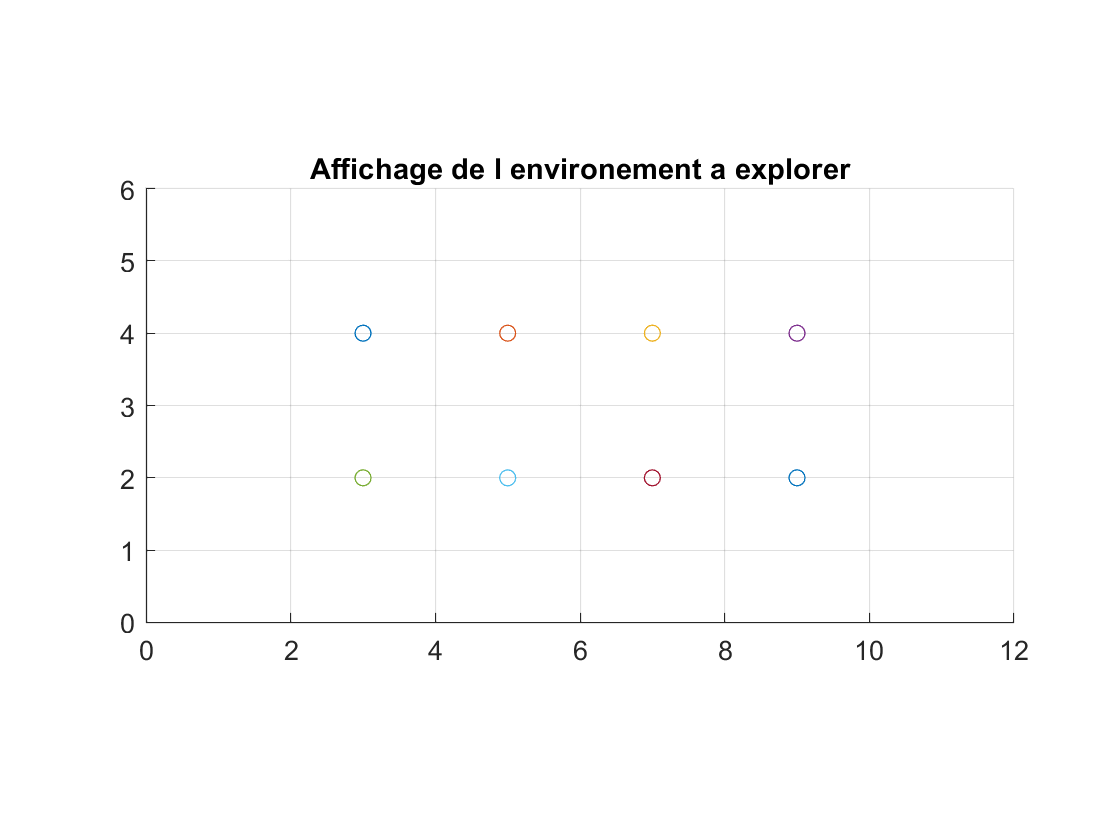


% Affichage de la carte
for k = 1 : length(Lm)
    figure(1)
    scatter(Lm(1,k),Lm(2,k))
    title("Affichage de l environement a explorer")
    axis equal
    xlim([0 12])
    ylim([0 6])   
    hold on
    grid on
end
hold off

## Creation d une commande pour le robot

Le vecteur Uk contient la commande pour chaque instant k la [(TauXk,TauYk)',Rhok]'

w=-pi; % Angle de rotation
deltaT=0.01; % Echelle de temps
X=1; % Deplacement d une unite

% Matrice de passage homegene pour les rotations autour de l axe Z 
Fr =[cos(w*deltaT) ,-sin(w*deltaT) , 0 1; sin(w*deltaT) cos(w*deltaT), 0 -1; 0 , 0, 1, 0; 0,0,0,1 ]

Fr =     0.9995    0.0314         0    1.0000
   -0.0314    0.9995         0   -1.0000
         0         0    1.0000         0
         0         0         0    1.0000


Fr2 =[cos(w*deltaT) ,-sin(w*deltaT) , 0, -1; sin(w*deltaT) cos(w*deltaT), 0, -1; 0, 0, 1, 0; 0,0,0,1 ] 

Fr2 =     0.9995    0.0314         0   -1.0000
   -0.0314    0.9995         0   -1.0000
         0         0    1.0000         0
         0         0         0    1.0000



Ft=[eye(3); zeros(1,3)]; 
Ft=[Ft,[X;zeros(2,1);1]] % Matrice de passage homegene pour une translation sur x

Ft =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


Ft2=[eye(3); zeros(1,3)];
Ft2=[Ft2,[-X;zeros(2,1);1]]% Matrice de passage homegene pour le retour en translation sur x

Ft2 =      1     0     0    -1
     0     1     0     0
     0     0     1     0
     0     0     0     1


## Modele cinematique du robot non-holonome

### Premier essai avec un modèle linéaire 

On utilise des matrices homogènes pour calculer le déplacement à l'instant k+1. On décompose le mouvement en une translation suivi de deux rotations et enfin une translation de retour.

Xreel(:,1)=[3;5;0;1] % Initialisation

Xreel =      3
     5
     0
     1


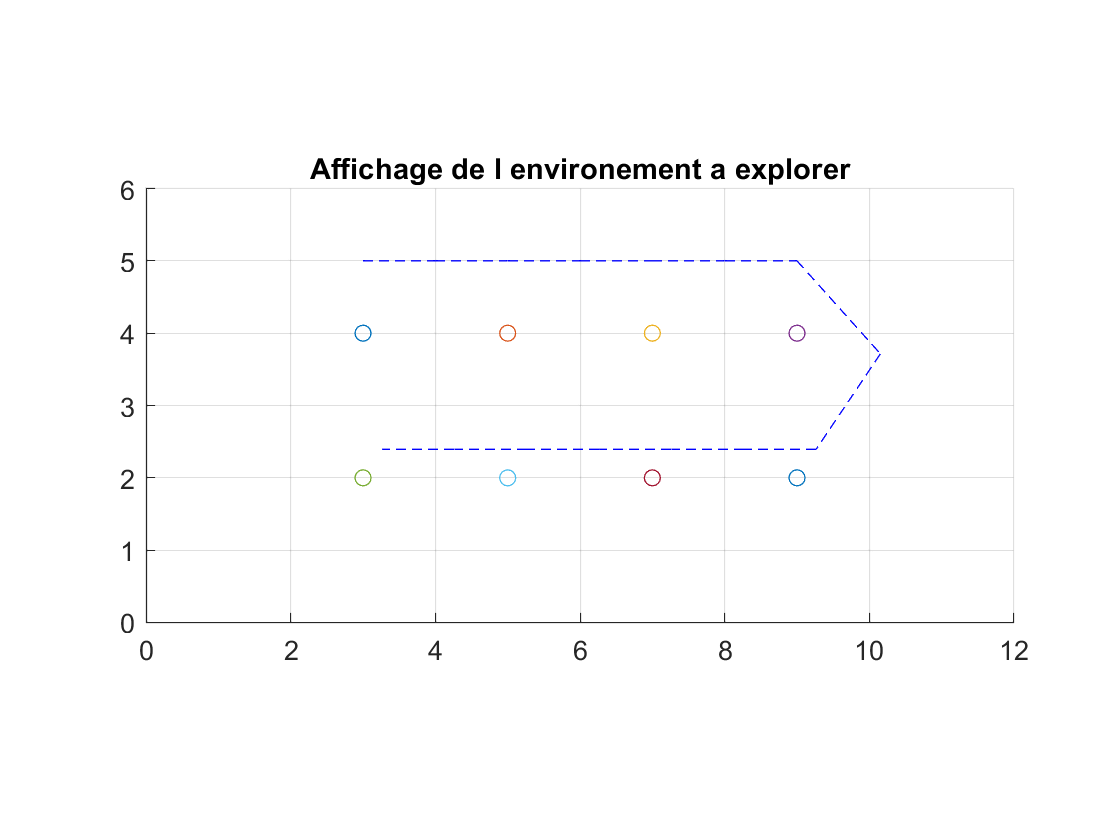


% Deplacement en ligne droite
for k=2:7
    Xreel(:,k)=Ft*Xreel(:,k-1);    
end

% Rotations
k=8;
Xreel(:,k)=Fr*Xreel(:,k-1);    
k=9;
Xreel(:,k)=Fr2*Xreel(:,k-1);    

% Retour en ligne droite
for k=10:16
    Xreel(:,k)=Ft2*Xreel(:,k-1); 
end


% Affichage de la trajectoire
for k = 1:length(Xreel)-1
    hold on
    plot(Xreel(1,max(k-1,1):k),Xreel(2,max(k-1,1):k),'--b');
    drawnow
    %pause(deltaT)
end

hold off

### Deuxième essai avec une modèle non linéaire

L'avantage d'implémenter un filtrage de Kalman étendu est la possibilité de retouver le vecteur caché d'un dynamique non linéaire. Nous allons à présent considérer le modèle non linéaire de la cinématique du robot pour générer les données. Nous définissons tout d'abord un vecteur contenant les commandes Uk=[(Txk,Tyk)',rhok]' à délivrer au robot mobile. Notons que le vecteur caché d'état Rx est en fonction Rxk,Ryk et THETAk ainsi que des positions des amers. On défini une matrice de passage homgène que l'on mettra à jour à chaque instant.

#### Ajout d un bruit sur les dynamiques

% Matrice des commandes deterministes pour effectuer le mouvement en U autour des amers
Uk=[1 1 1 1 1 1 1 1  1 1 1 1         1 1 1 1 1 1 1;
    0 0 0 0 0 0 0 0  0 0 0 0         0 0 0 0 0 0 0;
    0 0 0 0 0 0 0 0  w/4 w/4 w/4 w/4 0 0 0 0 0 0 0];


mX0 = [3;5;0]; %Espérance du vecteur d etat postionnant, en moyenne, le robot en position (3,5) avec une orientation de 0
PX0 = diag([.1 .2 .2e-2]); %Matrice de covariance de l etat initial
Qw = diag([.03^2 .03^2 (1e-10)^2]); %Covariance du bruit de dynamique
Rv = diag([.1^2 .1^2]);%Covariance du bruit de mesure
%Chol(A) renvoi la factorisation de Choleski telle que A=R'*R avec R
%trangulaire superieure
%Il resulte de randn le resultat d un tirage au sort gaussien


%Bruits
Wk = chol(Qw)'*randn(3,length(Uk)); %Loi Gaussienne du bruit de dynmaique
Vk = chol(Rv)'*randn(2,length(Uk)); %Loi Gaussienne du bruit de mesure


%Position incertaine a l initial initial
Xrobt (:,1)=mX0+chol(PX0)'*randn(3,1); %Etat bruite initial du robot (sans considerer les amers)



#### Calcul du vecteur d etat bruite

La dynamique bruitée du robot à l'nstant k depédent de la dynamique incertaine précédente à l'instant (k-1). Afin de faciliter les calculs, nous considérons le vecetrur d'état sans les amers compris.

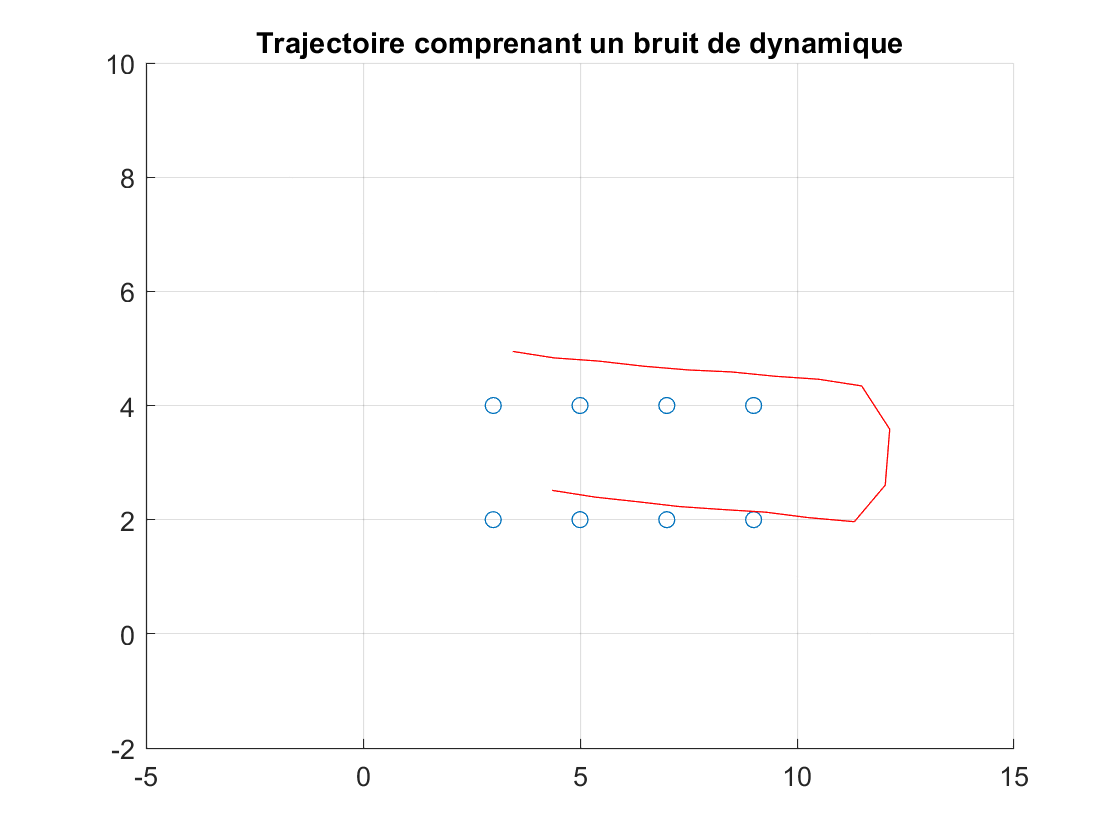

for k=2:length(Uk)
    % Vecteur Gr courant a l instant k
    Gr=[  Uk(1,k)*cos(Xrobt(3,k-1))-Uk(2,k)*sin(Xrobt(3,k-1));
          Uk(1,k)*sin(Xrobt(3,k-1))+Uk(2,k)*cos(Xrobt(3,k-1));
                           Uk(3,k)
       ];

    % Cinematique du robot avec bruit dynamique de Wk~N(0,Qw)
    Xrobt(:,k)=Xrobt(:,k-1)+Gr+Wk(:,k);      
end


figure()
scatter(Lm(1,:),Lm(2,:)) %Affichage des amers
axis([-5 15 -2 10])
grid on
hold on
title("Trajectoire comprenant un bruit de dynamique")
% Affichage de la trajectoire
for k = 1:length(Xrobt)
    plot(Xrobt(1,max(k-1,1):k),Xrobt(2,max(k-1,1):k),'-r');
    drawnow
end

hold off

## Modele d observation

La découverte des amers se fait suivant un modèle d'observation entaché d'un bruit Gaussien.

for k=1:8
    hk=[sqrt((Lm(1,k)-Xrobt(1,k))^2+(Lm(2,k)-Xrobt(2,k))^2);
        atan2(Lm(2,k)-Xrobt(2,k),(Lm(1,k)-Xrobt(1,k)))];
end


Zk=hk+Vk; %Mesure des robot avec bruit de Vk~N(0,Rv)

## Génération d un champs de vision limite

for k=1:length(Xrobt)
    if hk(1,k)<=2 % Distance euclidienne entre le robot et un amer inferieure a 2m
        Xcache(:,k)=[Xrobt(:,k),hk(:,k)] %Ajout de l amer a l etat cache
    else 
        Xcache(:,k)=[Xrobt(:,k),nan(2,1)];
        
    end

end

Unrecognized function or variable 'Nan'.



% deltaT=0.01;
% % Affichage de la carte
% for k = 1 : length(Lm)
%     figure(2)
%     %scatter(Lm(1,k),Lm(2,k))
%     rectangle('Position',[Lm(1,k) Lm(2,k) 0.25 0.25],'Curvature',0.2,'FaceColor', [0.01 0.01 0.01])
%     title("Affichage du champ de vision")
%     axis equal
%     xlim([0 15])
%     ylim([0 10])   
%     hold on
%     grid on
% end

## Filtrage de Kalman Etendu (EKF)

%    Ex=[eye(3) zeros(3,2*M)];   
%     % Covariance d un bruit blanc centre et statistiquement raisonnable
%     V=[.05^2 .05^2]; 
%     
%     for i=1:M
%      Qk=diag(V);     
%     end
%     
%       M=0; % Nombre d amers connus 
%     
%     % Incrementation de V en meme temps que M 